nii_dir = '/home/songsichen123/NFBS/mri';
imageDir = '/home/songsichen123/NFBS/train/data';
labelDir = '/home/songsichen123/NFBS/train/label';

delete(fullfile(imageDir,'*'));
delete(fullfile(labelDir,'*'));
files = dir(nii_dir);
masks = {files(cellfun(@(x) x==0,{files.isdir}) & cellfun(@(x) contains(x,'mask'),{files.name})).name};
images = {files(cellfun(@(x) x==0,{files.isdir}) & cellfun(@(x) ~contains(x,'mask'),{files.name})).name};
masks=sort(masks);
images=sort(images);

counter=1;
for i = 1:length(masks)
    i
    image_file_name = fullfile(nii_dir,images{i});
    mask_file_name = fullfile(nii_dir,masks{i});
    image = permute(niftiread(image_file_name),[1 3 2]);
    mask = permute(niftiread(mask_file_name),[1 3 2]);
    for z = 20:165
        image_slice = image(:,:,z);
        mask_slice = mask(:,:,z);
        imwrite(uint16(image_slice),fullfile(imageDir,strcat( 'img_',sprintf( '%06d', counter ),'.png')))
        imwrite(uint8(mask_slice),fullfile(labelDir,strcat('label_' ,sprintf( '%06d', counter ),'.png')))
        counter = counter + 1;
    end
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

z=160;
tmp = image(:,:,z);
sum(tmp(:))

ans = single
3049777

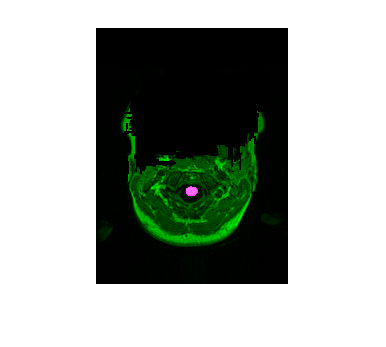

imshowpair(image(:,:,z)/200,mask(:,:,z)==1);

size(image)

ans =    256   192   256


imageSize = [256 192 1];
numClasses = 2;
encoderDepth = 3;
lgraph = unetLayers(imageSize,numClasses,'EncoderDepth',encoderDepth);
lgraph = replaceLayer(lgraph,'ImageInputLayer',[imageInputLayer(imageSize, "Name",'ImageInputLayer',"Normalization","zscore")]);
lgraph = replaceLayer(lgraph,'Segmentation-Layer',[pixelClassificationLayer('Name','Segmentation-Layer','Classes',["brain","background"], ...
  'ClassWeights', [4.3,1])]);

imds = imageDatastore(imageDir);
classNames = ["brain","background"];
labelIDs   = [1 0];
pxds = pixelLabelDatastore(labelDir,classNames,labelIDs);
ds = pixelLabelImageDatastore(imds,pxds,"OutputSize",imageSize,'outputSizeMode','centercrop');


options = trainingOptions('sgdm', ...
    'InitialLearnRate',1.7e-3, ...
    'MaxEpochs',200, ...
    'MiniBatchSize',64,...
    "Shuffle","every-epoch",...
    'VerboseFrequency',10, ...
    'Plots','training-progress');

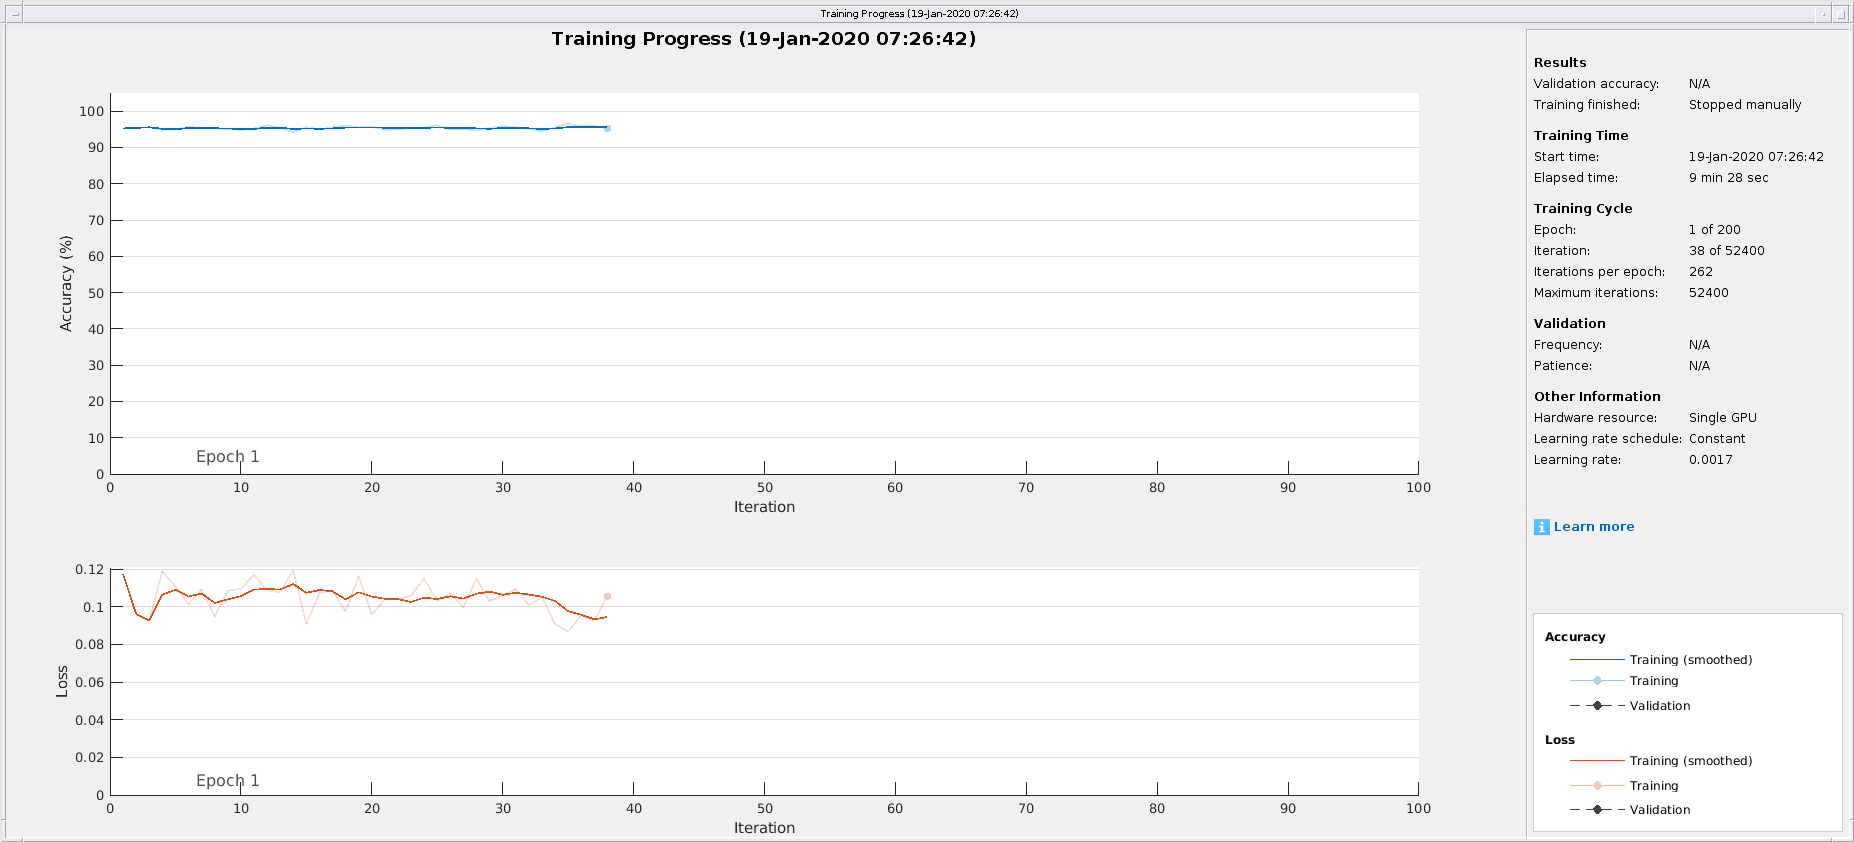

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:15 |       95.21% |       0.1173 |          0.0017 |
|       1 |          10 |       00:02:30 |       94.82% |       0.1095 |          0.0017 |
|       1 |          20 |       00:05:00 |       95.70% |       0.0959 |          0.0017 |
|       1 |          30 |       00:07:29 |       95.95% |       0.1059 |          0.0017 |
|       1 |          38 |       00:09:28 |       95.21% |       0.1057 |          0.0017 |
|========================================================================================|


net2 =   DAGNetwork with properties:

         Layers: [46×1 nnet.cnn.layer.Layer]
    Connections: [48×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}


net2 = trainNetwork(ds,lgraph,options)

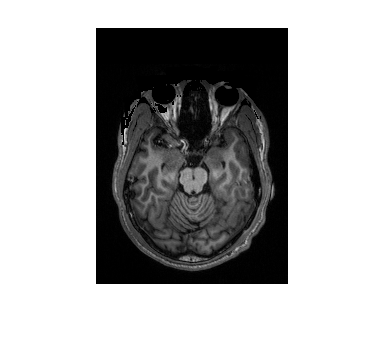

test_img = imread('~//NFBS/train/data/img_000099.png');
imshow(test_img*100)

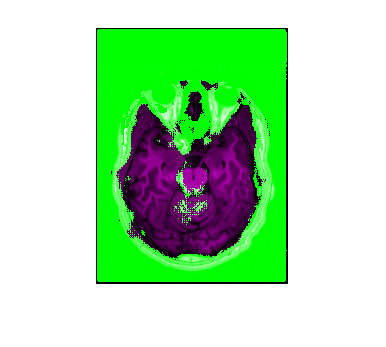

[C,scores]=semanticseg(test_img,net2);
%imagesc(scores>.98)
%BW = C == 'brain';
%figure
imshowpair(scores>.99,test_img)

imageSize = [224 224 3];
numClasses = 2;
lgraph = deeplabv3plusLayers(imageSize,numClasses,'resnet18');

lgraph = replaceLayer(lgraph,'data',[imageInputLayer(imageSize, "Name",'ImageInputLayer',"Normalization","zscore")]);
lgraph = replaceLayer(lgraph,'classification',[pixelClassificationLayer('Name','Segmentation-Layer','Classes',["brain","background"], ...
  'ClassWeights', [4.3,1])]);

imds = imageDatastore(imageDir);
classNames = ["brain","background"];
labelIDs   = [1 0];
pxds = pixelLabelDatastore(labelDir,classNames,labelIDs);
ds = pixelLabelImageDatastore(imds,pxds,"OutputSize",imageSize,'ColorPreprocessing','gray2rgb');


options = trainingOptions('sgdm', ...
    'InitialLearnRate',2e-3, ...
    'MaxEpochs',200, ...
    'MiniBatchSize',64,...
    "Shuffle","every-epoch",...
    'VerboseFrequency',10, ...
    'Plots','training-progress');

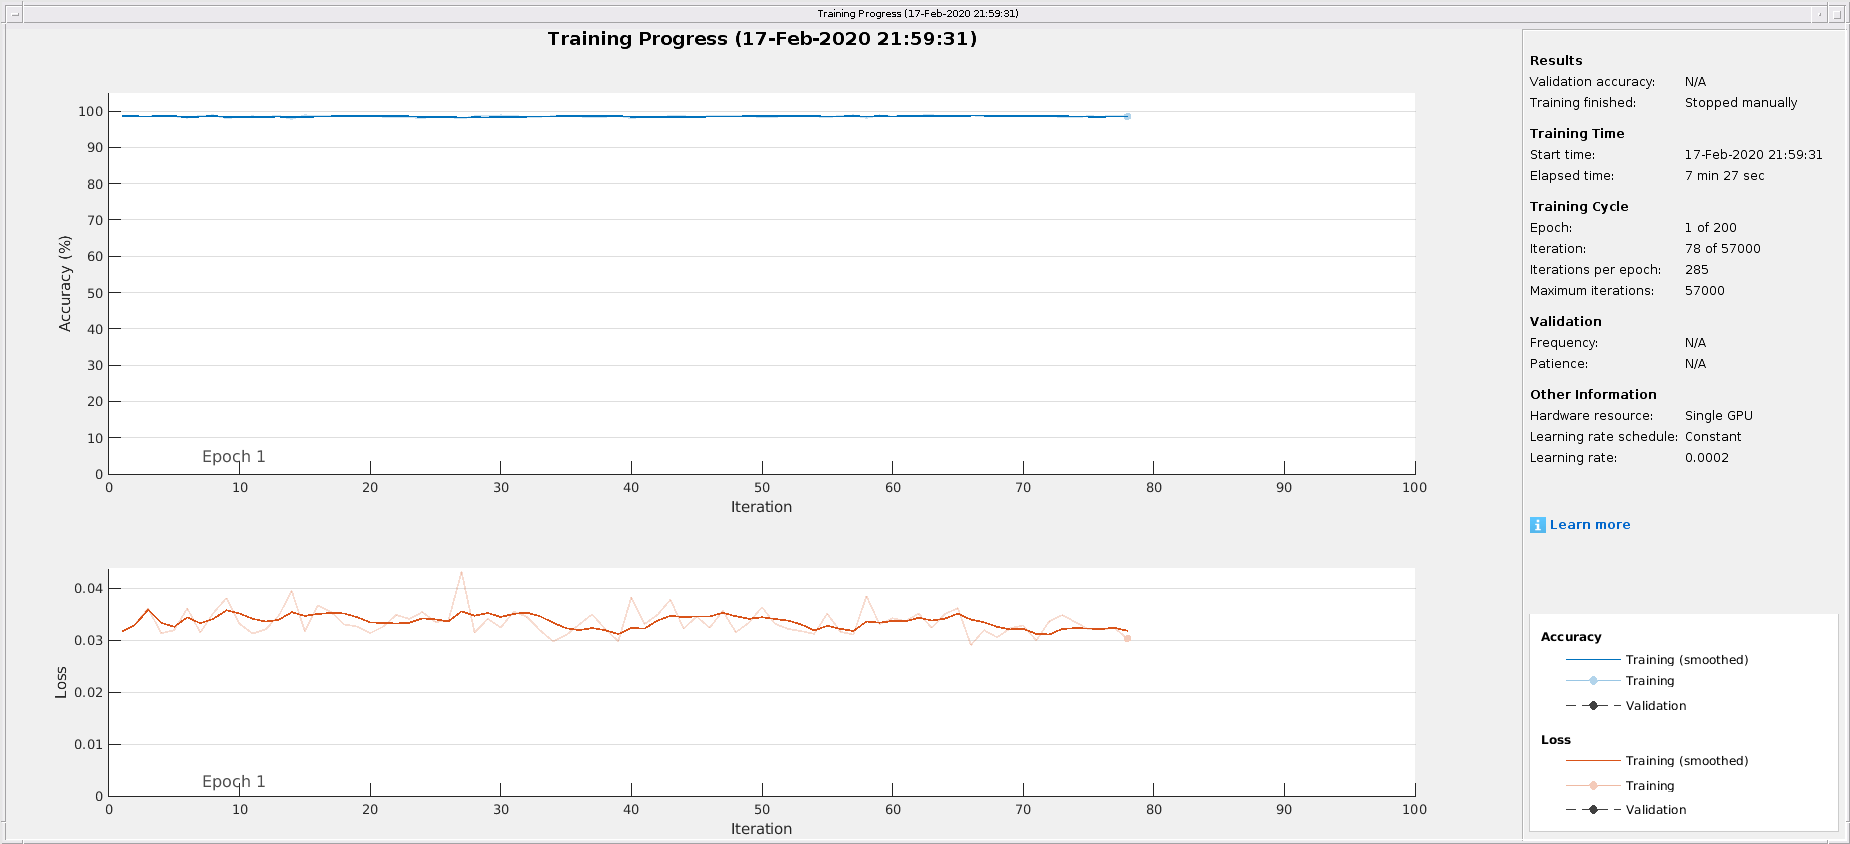

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |       98.57% |       0.0317 |          0.0002 |
|       1 |          10 |       00:00:58 |       98.42% |       0.0331 |          0.0002 |
|       1 |          20 |       00:01:55 |       98.69% |       0.0313 |          0.0002 |
|       1 |          30 |       00:02:52 |       98.84% |       0.0324 |          0.0002 |
|       1 |          40 |       00:03:50 |       98.03% |       0.0382 |          0.0002 |
|       1 |          50 |       00:04:47 |       98.35% |       0.0363 |          0.0002 |
|       1 |          60 |  

net2 =   DAGNetwork with properties:

         Layers: [100×1 nnet.cnn.layer.Layer]
    Connections: [113×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}


net2 = trainNetwork(ds,layerGraph(net2),options)

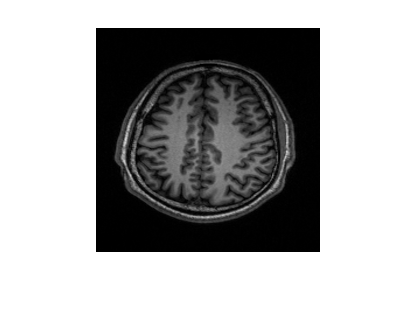

test_img = imresize(imread('~//NFBS/train/data/img_001359.png'),[224,224]);
imshow(test_img*100)

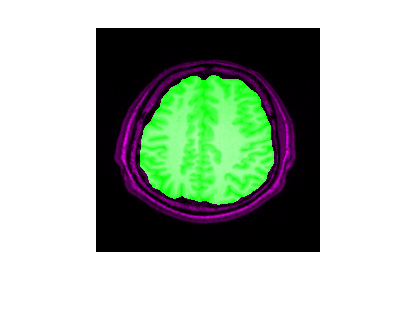

[C,scores]=semanticseg(test_img,net2);
%imagesc(scores>.98)
BW = C == 'brain';
%figure
imshowpair(BW,test_img)